# Graphene Euler-Bernoulli beam simulation

Parameters taken from the Dr. Wei's paper.

## Global constants

type = "ca";

L = 0.3e-3; % Dr. Wei
rho = 2.1e3; % Dr. Wei
E = 1e12; % young's modulus, general
sigma_max = 0.13e12; % Dr. Wei paper
D = -(E^2)/(4*sigma_max); % nonlinear elastic modulus
I1 = 5.21e-16; % 
I2 = 9.77e-18; % 

if type == "ca"
    F=10e6;
elseif type == "cc"
    F=100e6;
elseif type == "ss"
    F=10e6;
end

A = (5e-5)^2; % cross-section area (b*h)
B = E*I1;
C = D*I2;
C3 = 1/(12*C^2*F)*(6*B*C*F*L - B^3 + (B^2-4*C*F*L)^(3/2));
C4 = 1/(12*C^2*F)*(B^3*L -3*B*C*F*L^2 + 1/(10*C*F)*((B^2-4*C*F*L)^(5/2) - B^5)) + L*C3;

## FEM config

Nb = 4; % number of dof per element
gauss_points_num = 8;
master = [0 1];
Npts = 100; % for plotting

% linear elements
coeffs =   [1,0,-3,2; 
            0,1,-2,1;
            0,0,3,-2;
            0,0,-1,1];

## Matrix assembly

NEL = 20;
h = L/NEL;

% basis functions on the master element
N = basis_functions(coeffs);
d2_N = basis_derivatives(coeffs, 2);
d3_N = basis_derivatives(coeffs, 3);

% global nodes
xs = linspace(0,L,NEL+1);

% mesh sizes
hs = zeros(NEL,1);
for i=1:NEL
    hs(i) = xs(i+1) - xs(i);
end

% element nodes
es = zeros(NEL,2);
for i=1:NEL
    es(i,:) = [xs(i) xs(i+1)];
end

% local stiffness and mass matrices
Kl = zeros(Nb,Nb,NEL);
Ml = zeros(Nb,Nb,NEL);
fl = zeros(Nb,1,NEL);
for k=1:NEL
    for i=1:Nb
        for j=1:Nb
            Kl(i,j,k) = 1 / (hs(k))^3 * gauss(@(x) d2_N(i,x) * d2_N(j,x), master(1), master(2), gauss_points_num);
            Ml(i,j,k) =      hs(k)    * gauss(@(x)    N(i,x) *    N(j,x), master(1), master(2), gauss_points_num);
        end
        fl(i,1,k)     = F *  hs(k)    * gauss(@(x) N(i,x), master(1), master(2), gauss_points_num);
    end
end

% Global matrices and force term
Kn = (NEL+1)*2;
K = zeros(Kn,Kn); M = zeros(Kn,Kn);
f = zeros(Kn,1);

for i=1:NEL
    K(2*i-1:2*i+Nb-2,2*i-1:2*i+Nb-2) = K(2*i-1:2*i+Nb-2,2*i-1:2*i+Nb-2) + Kl(1:Nb,1:Nb,i);
    M(2*i-1:2*i+Nb-2,2*i-1:2*i+Nb-2) = M(2*i-1:2*i+Nb-2,2*i-1:2*i+Nb-2) + Ml(1:Nb,1:Nb,i);
    f(2*i-1:2*i+Nb-2,1) = f(2*i-1:2*i+Nb-2,1) + fl(1:Nb,1,i);
end

K1 = E*I1*K;
K2 = D*I2*K;
if type == "ca"
    K2 = K2(3:end,3:end);
elseif type == "cc"
    K2 = K2(3:end-2,3:end-2);
elseif type == "ss"
    K2(1,:) = []; K2(:,1) = []; K2(end-1,:) = []; K2(:, end-1) = [];
end
M = rho*M;

## Solver prep

% IC
% v = @(x) 1/(12*C^2*F)*(B^2*x-6*B*C*F*L*x+3*B*C*F*x^2-B^3*L+3*B*C*F*L^2) - 1/(120*C^3*F^2) * ((B^2-4*C*F*L+4*C*F*x)^(5/2)-B^5) + C3*(x-L) + C4;
% dv = @(x) 1/(12*C^2*F)*(B^2-6*B*C*F*L+6*B*C*F*x) - 1/(120*C^3*F^2) * (5/2)*(B^2-4*C*F*L+4*C*F*x)^(3/2)*4*C*F + C3;

% v = @(x) 1e-6.*x.^2;
% dv = @(x) 2e-6.*x;
% w = @(x) 0;
% dw = @(x) 0;

v = @(x) 0;
dv = @(x) 0;
w = @(x) 0;
dw = @(x) 0;

vs = project(v, dv, xs);
ws = project(w, dw, xs);

T0 = 0; 
timescale = 1e-4;
if type == "ca"
    Tf = 5*timescale;
    tau = Tf/100;
elseif type == "cc"
    Tf = .75*timescale;
    tau = Tf/75;
elseif type == "ss"
    Tf = 1.75*timescale;
    tau = Tf/70;
end

Ntsteps = round(Tf/tau+1);

lambda = tau^2;

Amat = M+lambda/4*K1;
Bmat = 2*M-lambda/2*K1;
f = lambda*f;

if type == "ca"
    K1 = K1(3:end,3:end);
    Amat = sparse(Amat(3:end, 3:end));
    Bmat = sparse(Bmat(3:end, 3:end));
    f = f(3:end, 1);
elseif type == "cc"
    K1 = K1(3:end-2,3:end-2);
    K1 = sparse(K1); K2 = sparse(K2);
    Amat = sparse(Amat(3:end-2, 3:end-2));
    Bmat = sparse(Bmat(3:end-2, 3:end-2));
    f = f(3:end-2, 1);
elseif type == "ss"
    K1(1,:) = []; K1(:,1) = []; K1(end-1,:) = []; K1(:, end-1) = [];
    K1 = sparse(K1); K2 = sparse(K2);
    Amat(1,:) = []; Amat(:,1) = []; Amat(end-1,:) = []; Amat(:, end-1) = [];
    Bmat(1,:) = []; Bmat(:,1) = []; Bmat(end-1,:) = []; Bmat(:, end-1) = [];
    Amat = sparse(Amat);
    Bmat = sparse(Bmat);
    f(1) = []; f(end-1) = [];
end

% Use fixed point iteration for u
% Start with the initial guess

us = zeros(Kn,Ntsteps);
us(:,1) = vs;

% implicit scheme
options = optimset('Display','off');

if type == "ca"
    func1 = @(soln) 2*Amat*soln - (Bmat*us(3:end,1) + 2*tau*Amat*ws(3:end) + f - lambda*K2*hfun((soln + us(3:end,1) - tau*ws(3:end,1))/2));
    us(3:end,2) = fsolve(func1, ones(Kn-2,1),options);
    
    for j=3:Ntsteps
        func2 = @(soln) Amat*soln - (Bmat*us(3:end,j-1) - Amat*us(3:end,j-2) + f - lambda*K2*hfun((soln + 2*us(3:end,j-1) + us(3:end,j-2))/4));
        us(3:end,j) = fsolve(func2,ones(Kn-2,1),options);
    end
elseif type == "cc"
    func1 = @(soln) 2*Amat*soln - (Bmat*us(3:end-2,1) + 2*tau*Amat*ws(3:end-2) + f - lambda*K2*hfun((soln + us(3:end-2,1) - tau*ws(3:end-2,1))/2));
    us(3:end-2,2) = fsolve(func1, ones(Kn-4,1),options);
    
    for j=3:Ntsteps
        func2 = @(soln) Amat*soln - (Bmat*us(3:end-2,j-1) - Amat*us(3:end-2,j-2) + f - lambda*K2*hfun((soln + 2*us(3:end-2,j-1) + us(3:end-2,j-2))/4));
        us(3:end-2,j) = fsolve(func2,ones(Kn-4,1),options);
    end
elseif type == "ss"
    ust = zeros(Kn-2,Ntsteps);
    ust(1:end-1,1) = vs(2:end-2,1); ust(end,1) = vs(end,1);
    func1 = @(soln) 2*Amat*soln - (Bmat*ust(:,1) + 2*tau*Amat*[ws(2:end-2,1);ws(end,1)] + f - lambda*K2*hfun_ss(([0;soln(1:end-1,1);0;soln(end,1)] + us(:,1) - tau*ws)/2));
    ust(:,2) = fsolve(func1, ones(Kn-2,1),options);
    us(:,2) = [0;ust(1:end-1,2);0;ust(end,2)];
    
    for j=3:Ntsteps
        func2 = @(soln) Amat*soln - (Bmat*ust(:,j-1) - Amat*ust(:,j-2) + f - lambda*K2*hfun_ss(([0;soln(1:end-1,1);0;soln(end,1)] + 2*us(:,j-1) + us(:,j-2))/4));
        ust(:,j) = fsolve(func2,ones(Kn-2,1),options);
        us(:,j) = [0;ust(1:end-1,j);0;ust(end,j)];
    end
end

us2 = zeros(Kn,Ntsteps);
us2(:,1) = vs;

if type == "ca"
    us2(3:end,2) = (2*Amat)\(Bmat*us2(3:end,1) + 2*tau*Amat*ws(3:end) + f);
    
    for j=3:Ntsteps
        us2(3:end,j) = Amat\(Bmat*us2(3:end,j-1) - Amat*us2(3:end,j-2) + f); 
    end
elseif type == "cc"
    us2(3:end-2,2) = (2*Amat)\(Bmat*us2(3:end-2,1) + 2*tau*Amat*ws(3:end-2) + f);
    
    for j=3:Ntsteps
        us2(3:end-2,j) = Amat\(Bmat*us2(3:end-2,j-1) - Amat*us2(3:end-2,j-2) + f); 
    end
elseif type == "ss"
    us2t = zeros(Kn-2,Ntsteps);
    us2t(1:end-1,1) = vs(2:end-2,1); us2t(end,1) = vs(end,1);
    
    us2t(:,2) = (2*Amat)\(Bmat*us2t(:,1) + 2*tau*Amat*[ws(2:end-2,1);ws(end,1)] + f);
    
    for j=3:Ntsteps
        us2t(:,j) = Amat\(Bmat*us2t(:,j-1) - Amat*us2t(:,j-2) + f);
    end
    us2 = [zeros(1,Ntsteps); us2t(1:end-1,:); zeros(1,Ntsteps); us2t(end,:)];
end

xxxs = linspace(0,L,Npts);
u_full = zeros(length(xxxs),Ntsteps);
u_full2 = zeros(length(xxxs),Ntsteps);

for j=1:Ntsteps
    % local u coefficients
    u_locals = zeros(NEL, Nb);
    for i=1:NEL
        u_locals(i,1:end) = us(2*i-1: 2*i+Nb-2,j);
    end
    
    u_locals2 = zeros(NEL, Nb);
    for i=1:NEL
        u_locals2(i,1:end) = us2(2*i-1: 2*i+Nb-2,j);
    end
    
    % producing piecewise polynomial approximation
    
    u_vals = zeros(length(xxxs),1);
    for i=1:length(xxxs)
        u_vals(i) = u_fun(u_locals, xxxs(i), NEL, Nb, N, es, xs);
    end
    u_full(1:end,j) = u_vals;
    
    u_vals2 = zeros(length(xxxs),1);
    for i=1:length(xxxs)
        u_vals2(i) = u_fun(u_locals2, xxxs(i), NEL, Nb, N, es, xs);
    end
    u_full2(1:end,j) = u_vals2;
end

## Plotting

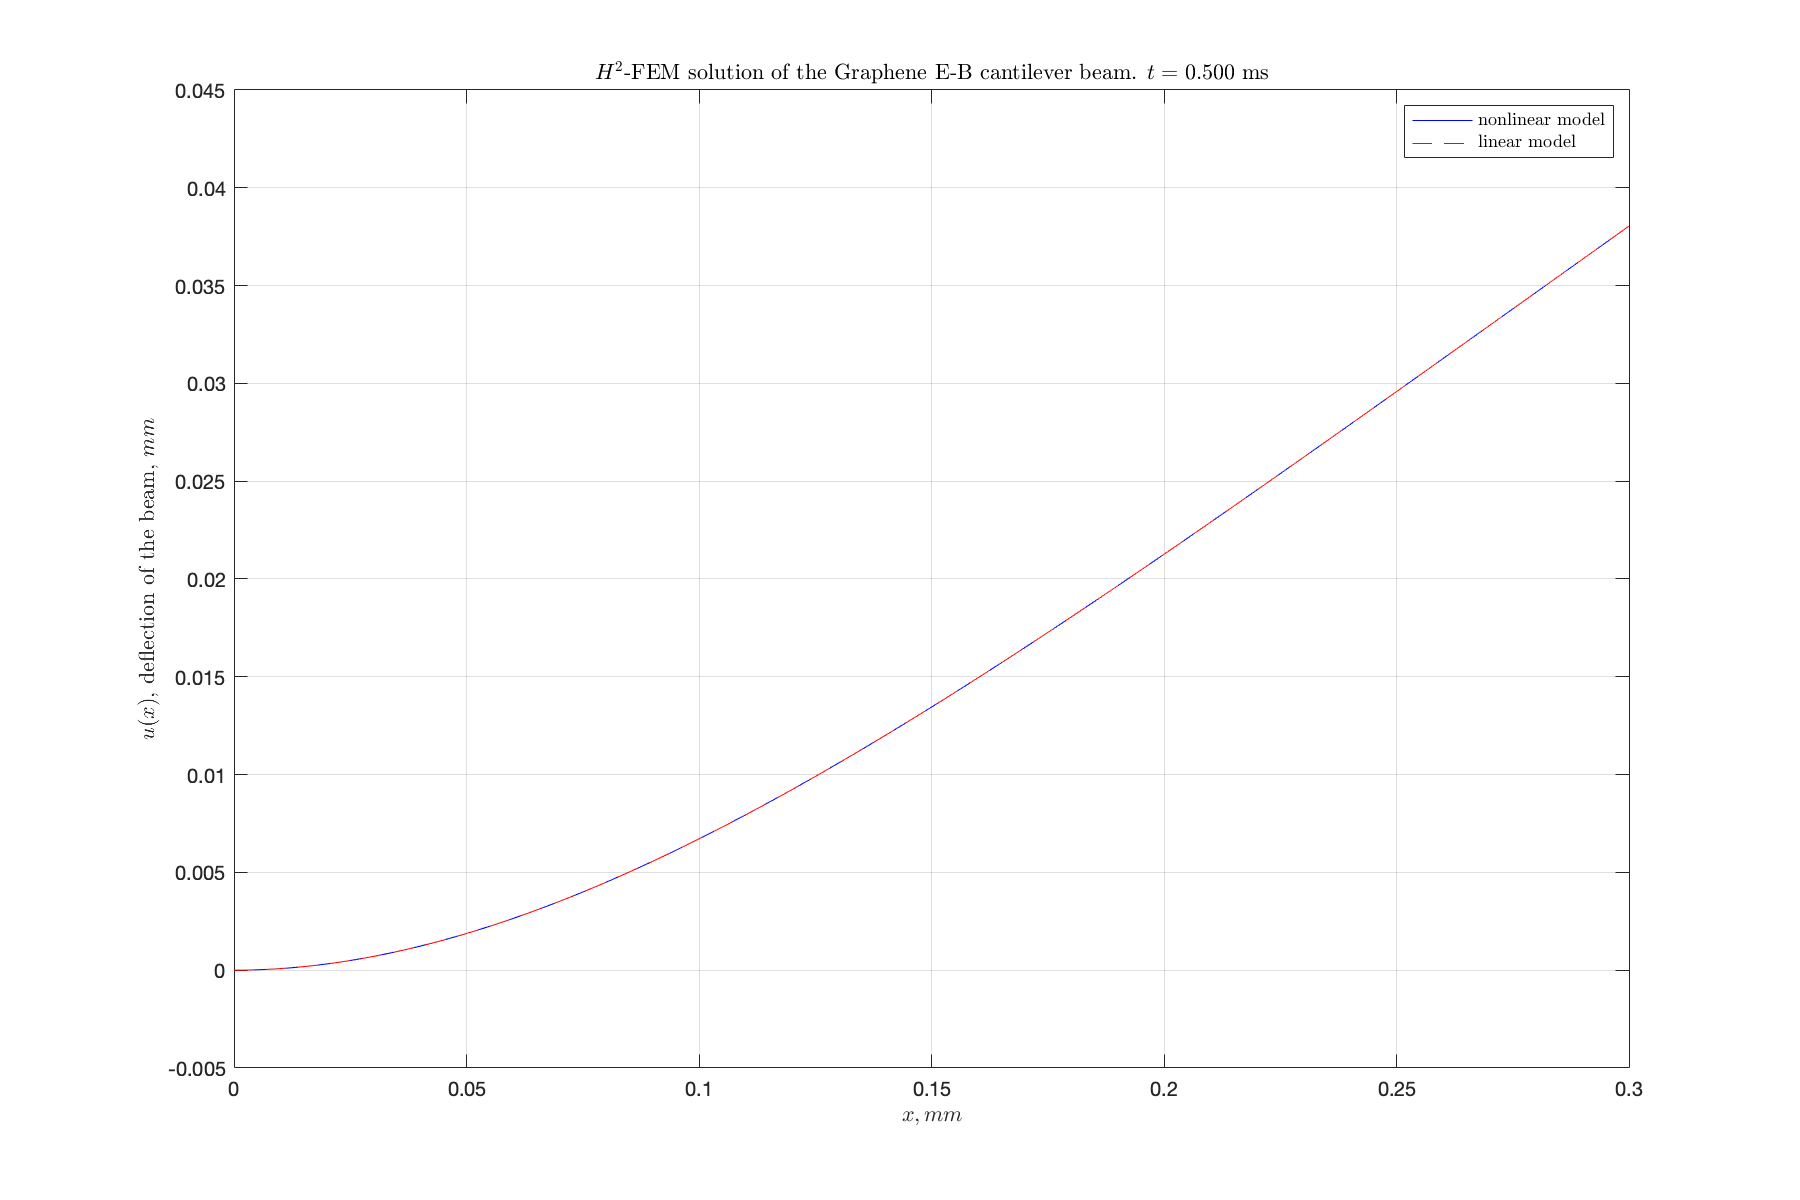

figure('Position', [10 10 900 600])
scale=1e-5;
for j=1:Ntsteps
    plot(xxxs*1e3,u_full(1:end,j)*1e3,'b-', xxxs*1e3,u_full2(1:end,j)*1e3,'r--') 
    grid on
    xlim([0 L]*1e3)
    if type == "ca"
        ylim([-.5*scale,4.5*scale]*1e3)
        ttl = sprintf("$H^2$-FEM solution of the Graphene E-B cantilever beam. $t=%.3f$ ms",tau*(j-1)*1e3);
    elseif type == "cc"
        ylim([-.05*scale,scale]*1e3)
        ttl = sprintf("$H^2$-FEM solution of the Graphene E-B doubly-clamped beam. $t=%.3f$ ms",tau*(j-1)*1e3);
    elseif type == "ss"
        ylim([-.05*scale,0.5*scale]*1e3)
        ttl = sprintf("$H^2$-FEM solution of the Graphene E-B simply-supported beam. $t=%.3f$ ms",tau*(j-1)*1e3);
    end
    title(ttl, "Interpreter","latex")
    xlabel('$x, mm$', "Interpreter","latex")
    ylabel('$u(x)$, deflection of the beam, $mm$', "Interpreter","latex")
    
    leg = legend('nonlinear model','linear model');    
    set(leg,'Interpreter','latex');    
    
    hold off
    pause(.05)
end

## FEM tools

function res = chi(e,x,xs) 
    res = false;
    if x > xs(e) && x <= xs(e+1)
        res = true;
    end
end

function res = xi(x,xe)
     res = (x - xe(1)) / (xe(2) - xe(1));
end

% assemble u(x) from u_i coefficients
function res = u_fun(u_locals, x, NEL, Nb, N, es, xs)
    res = 0;
    for i=1:NEL
        sm = 0;
        for j=1:Nb
            sm = sm + u_locals(i,j) * N(j,xi(x,es(i,:)));
        end
        sm = sm * chi(i,x,xs);
        res = res + sm;
    end
end

## Polynomial tools

function basis = basis_functions(coefficient_matrix)
    mat_size = length(coefficient_matrix);
    basis = @(index, x) coefficient_matrix(index,1:mat_size)*(x.^(0:mat_size-1))';
end

function der_mat = derivative_matrix(basis_order, derivative_order)
    der_mat = zeros(basis_order, basis_order);
    for i=derivative_order+1:basis_order
        prod = 1;
        for j=1:derivative_order
            prod = prod*(i-j);
        end
        der_mat(i-derivative_order,i) = prod;
    end
    der_mat = sparse(der_mat');
end

function res = basis_derivatives(coefficient_matrix, order)
    der_mat = derivative_matrix(length(coefficient_matrix), order);
    res = basis_functions(coefficient_matrix*der_mat);
end

function res = gauss(fun, a, b, order)
    [x,w] = lgwt(order,a,b);
    f = arrayfun(fun,x);
    res = sum(f.*w);
end

## Projection onto FE space

function proj = project(fun, dfun, xs)
    proj = zeros(2*length(xs),1);
    for i=1:length(xs)
        proj(2*i-1) =  fun(xs(i));
        proj(2*i)   = dfun(xs(i));
    end
end

function res = hfunc(x)
    res = abs(x)*x;
end

function res = d_hfunc(x)
    res = 2*abs(x);
end

% p-laplacian
function res = hfun(x)
    n = length(x);
    res = zeros(n,1);
    for i=1:n
        if rem(i, 2) == 1
            res(i) = hfunc(x(i));
        else
            res(i) = d_hfunc(x(i-1))*x(i);
        end
    end
end

function res = hfun_ss(x)
    n = length(x);
    res = zeros(n,1);
    for i=1:n
        if rem(i, 2) == 1
            res(i) = hfunc(x(i));
        else
            res(i) = d_hfunc(x(i-1))*x(i);
        end
    end
    res(1) = []; res(end-1) = [];
end